%% Re-cluster all compositional states across many GARD runs

nRuns    = 100;          % number of independent simulations
nSamples = 1000;         % total number of composomes to sample (optional)
NG       = 100;          % number of molecule types

% all_states = [];         % store all compositions (NG x totalSamples)
all_composomes = [];

for r = 1:nRuns
    fname = sprintf('data/GARD_run_seed_%03d.mat', r);
    if ~isfile(fname)
        warning('Missing %s, skipping.', fname);
        continue;
    end
    load(fname, 'o');
    trace = o.trace;                % NG × GEN composition matrix
    trace_frac = trace ./ max(sum(trace,1),1e-12); % normalize to fractions
    
    % find composome indices: where o.tags > 0
    comp_idx = find(o.tags > 0);
    if isempty(comp_idx)
        continue;
    end
    
    % sample random composomes (limited by what's available)
    nsamp = min(length(comp_idx), ceil(nSamples / nRuns));
    idx_sample = randsample(comp_idx, nsamp);
    
    % collect normalized compositions
    all_composomes = [all_composomes, trace_frac(:, idx_sample)];

    % Option A: use all generations (for full-space clustering)
    % all_states = [all_states, trace_frac];

    % Option B (recommended): sample subset per run for balance
    % nsamp = min(size(trace_frac,2), ceil(nSamples / nRuns));
    % idx   = randperm(size(trace_frac,2), nsamp);
    % all_states = [all_states, trace_frac(:, idx)];
end

% fprintf('Collected %d total states for re-clustering.\n', size(all_states,2));

%% Compute cosine similarity among all collected states
% norms = sqrt(sum(all_states.^2,1));
% simMatrix = (all_states' * all_states) ./ (norms' * norms);
fprintf('Collected %d composomes total.\n', size(all_composomes, 2));

Collected 742 composomes total.



%% Compute cosine similarity matrix
simMatrix = all_composomes' * all_composomes; % pairwise cosine similarities
simMatrix = simMatrix ./ (vecnorm(all_composomes)' * vecnorm(all_composomes));

%% Cluster all states together into new global compotypes
thr = 0.9;  % similarity threshold for composome membership
distMatrix = 1 - simMatrix;

Z = linkage(distMatrix, 'average');
T = cluster(Z, 'cutoff', 1 - thr, 'criterion', 'distance');

nCompotypes = max(T);
fprintf('Identified %d global compotypes across all simulations.\n', nCompotypes);

Identified 708 global compotypes across all simulations.


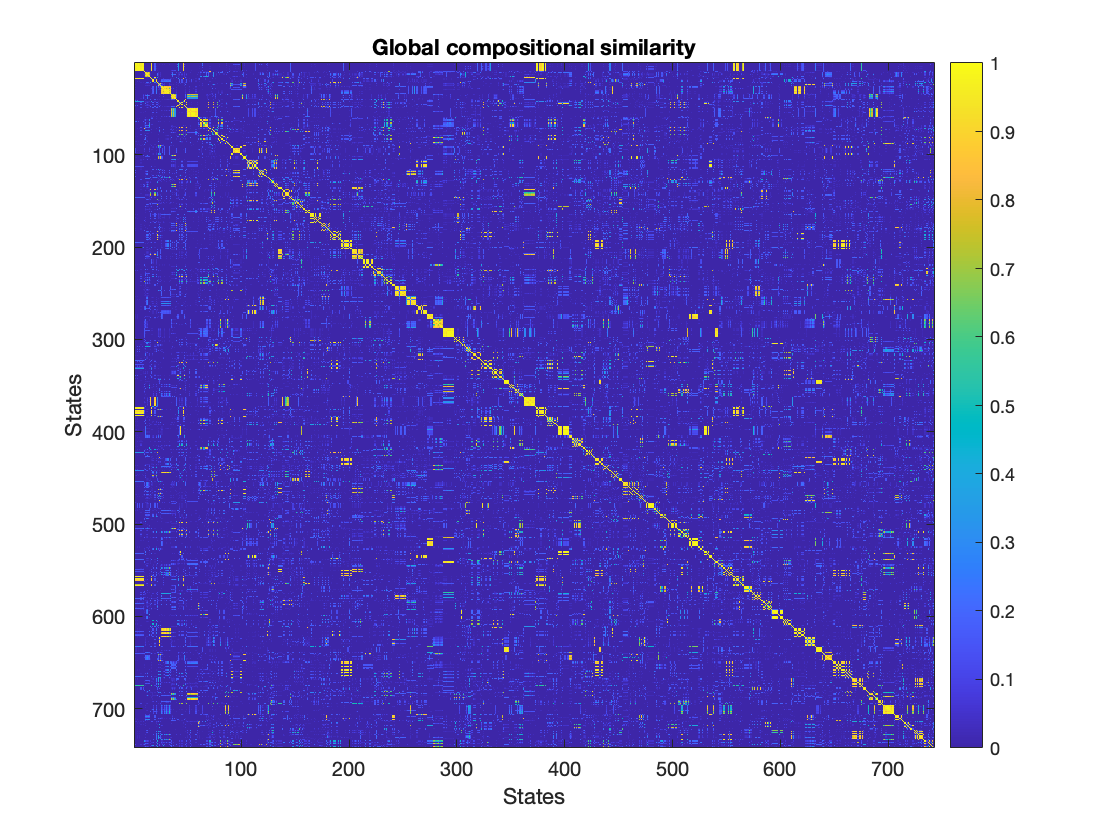


%% Compute representative compositions for each new compotype
% global_comps = zeros(NG, nCompotypes);
% for k = 1:nCompotypes
%     global_comps(:, k) = mean(all_states(:, T == k), 2);
% end

%% Visualization
figure;
imagesc(simMatrix);
title('Global compositional similarity');
xlabel('States'); ylabel('States');
colorbar;

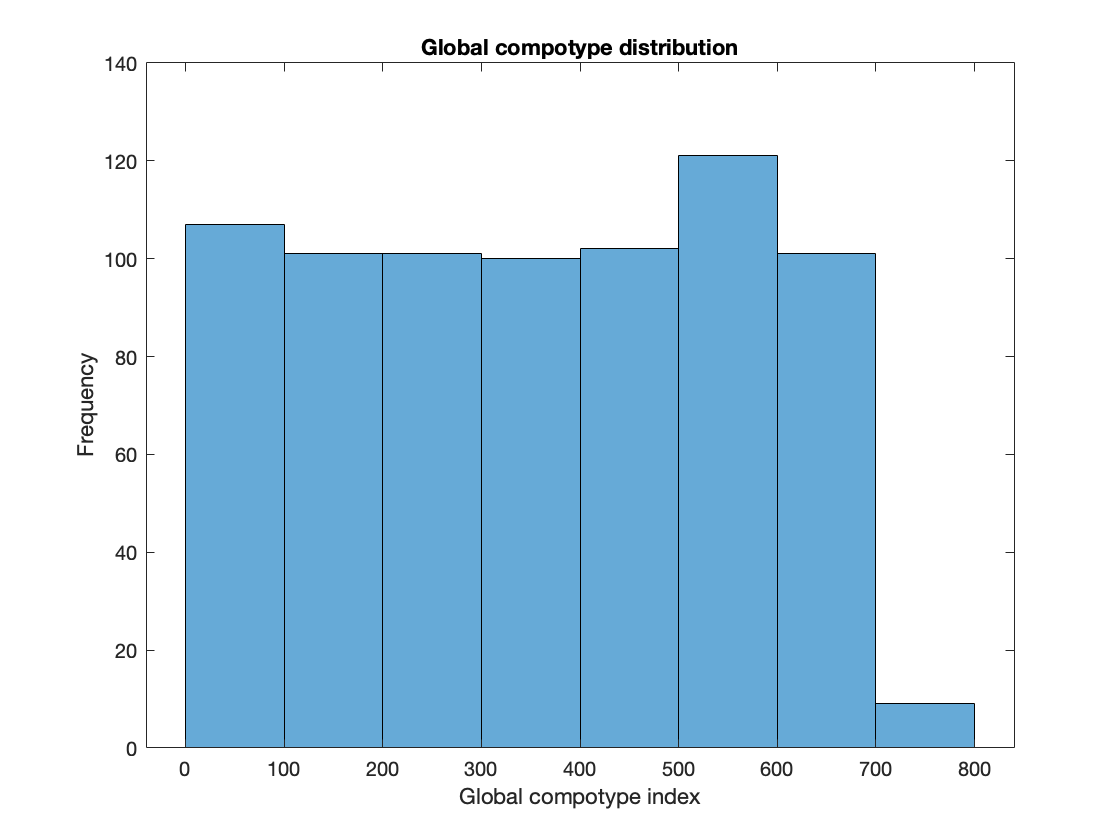


figure;
histogram(T);
xlabel('Global compotype index');
ylabel('Frequency');
title('Global compotype distribution');


%% Optional: save results
% save('GARD_global_clustering.mat', 'T', 'global_comps', 'simMatrix');